Q4

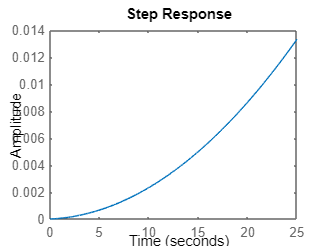

clc
clear
close

% Variable definitions and system creation
m = 5; % Slider mass
M = 25000; % Container mass
l = 8; % Rope length 
g = 9.81; % Acceleration due to gravity

% System Transfer Function is given by the numerator and denominator
% coefficients 
num = [0,0,0.2,0.2453];
den = [1,0,6.1325e+03,0,0];

[A,B,C,D] = tf2ss(num,den);

sys = ss(A,B,C,D);
step(sys);

Differences 

I have observed that this system is marginally stable unlike the system in section 2.2 which is a closed loop system that has feedback control. The poles of this system are on the imaginary axis. 

eig(A)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 +78.3103i
   0.0000 -78.3103i
